# CMSC828v Homework 6

DFS, BFS, and random graphs

## Problem 1. DFS and Connected Components in Random Graphs

n = 1000;
rs = 100;
zs = 0:0.1:4; % define a grid of z values
giant = zeros(length(zs),1);
nongiant = zeros(length(zs),1);

% compute experimental S(z) and <s> values
for i = 1:length(zs)
    z = zs(i);
    disp(['processing z=' num2str(z)]);
    p = z/(n-1);
    giant_z = zeros(rs,1);
    nongiant_z = zeros(rs,1);
    for r = 1:rs
        E = GenerateRandomGraph(n,p);
        C = ConnectedComponents(E);
        [maxv,~] = max(C); % find the largest component
        giant_z(r) = maxv;
        nongiant_z(r) = (sum(C)-maxv)/(length(C)-1);
    end
    giant(i) = mean(giant_z);
    nongiant(i) = mean(nongiant_z);
end

processing z=0
processing z=0.1
processing z=0.2
processing z=0.3
processing z=0.4
processing z=0.5
processing z=0.6
processing z=0.7
processing z=0.8
processing z=0.9
processing z=1
processing z=1.1
processing z=1.2
processing z=1.3
processing z=1.4
processing z=1.5
processing z=1.6
processing z=1.7
processing z=1.8
processing z=1.9
processing z=2
processing z=2.1
processing z=2.2
processing z=2.3
processing z=2.4
processing z=2.5
processing z=2.6
processing z=2.7
processing z=2.8
processing z=2.9
processing z=3
processing z=3.1
processing z=3.2
processing z=3.3
processing z=3.4
processing z=3.5
processing z=3.6
processing z=3.7
processing z=3.8
processing z=3.9
processing z=4


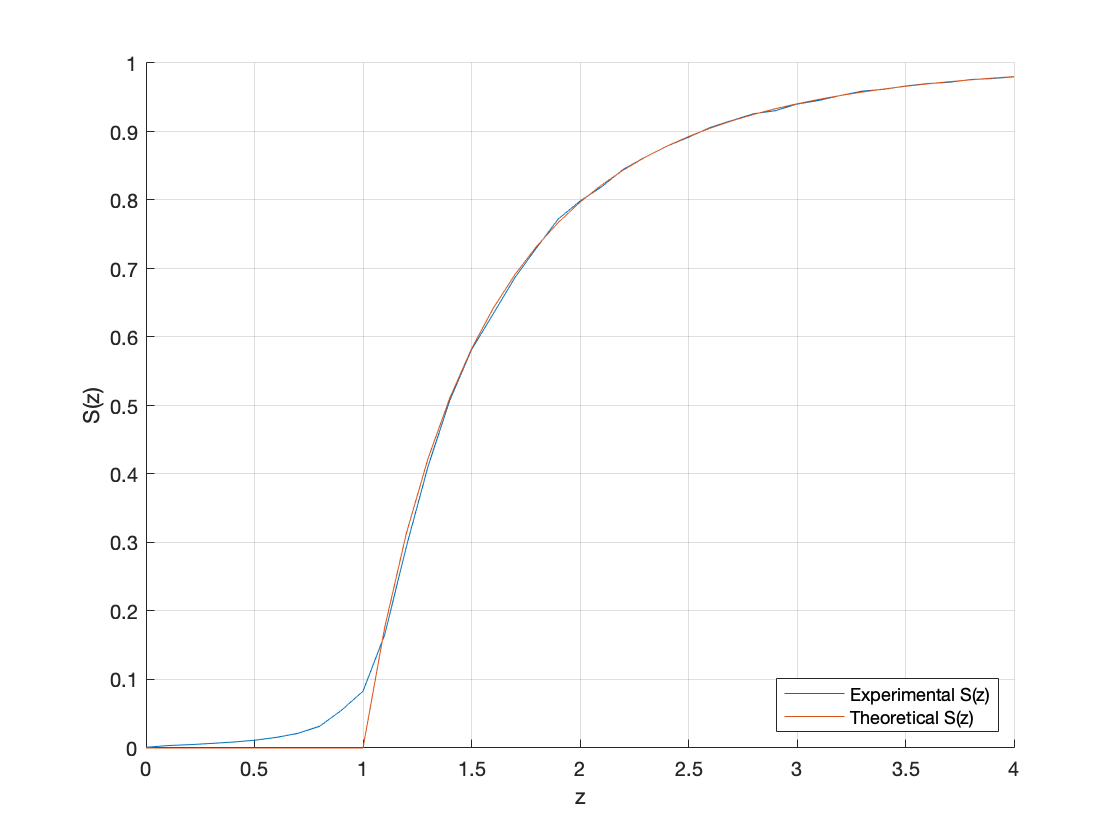


% compute theoretical S(z) and <s> values
zs = 0:0.1:4;
theoretical_Sz = zeros(size(zs));
theoretical_s = zeros(size(zs));
for i = 1:length(zs)
    z = zs(i);
    syms x;
    eqn = x == 1-exp(-z*x);
    S = solve(eqn,x);
    theoretical_Sz(i) = S;
    theoretical_s(i) = 1/(1-z+z*S);
end

% plot theoretical and experimental S(z)
figure; 
grid on;
hold on;
plot(zs,giant/1000,'DisplayName','Experimental S(z)');
plot(zs,theoretical_Sz,'DisplayName','Theoretical S(z)');
xlabel('z');
ylabel('S(z)');
legend('Location','southeast');
saveas(gcf,'figures/Sz.png');

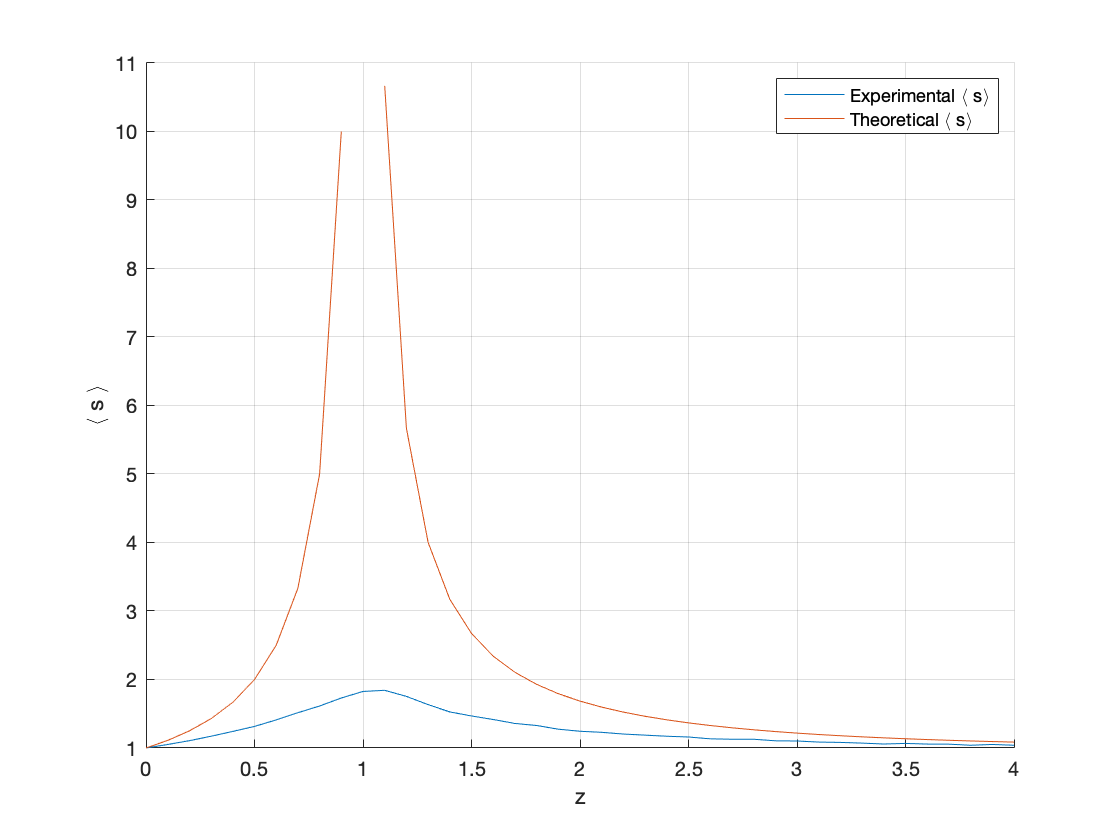


% plot theoretical and experimental <s>
figure; 
grid on;
hold on;
plot(zs,nongiant,'DisplayName','Experimental \langle s\rangle');
plot(zs,theoretical_s,'DisplayName','Theoretical \langle s\rangle');
xlabel('z');
ylabel('\langle s \rangle');
legend('Location','northeast');
saveas(gcf,'figures/s.png');